# Importing DATA

clear all; clc; 
format long g;
sensor_data= readmatrix('fort600.xlsx');
% sensordata = dlarray(sensor_data);
sensordata = sensor_data(1:1597,:);% To get 1600 points
Data_in = sensordata(1,1:8);
Data_in = [Data_in;sensordata(1,9:16)]

Data_in =                  4.3119979                0.93504871                 1.2126992                0.14990909                 1.3609625                 1.2958904                 1.4728005                -7.8152902
                 4.6370932                 1.3317006                 1.0280635                0.48291254                0.54450921                 1.7415827                0.65598598                -7.4425119


Data_in = [Data_in; sensordata(1,17:24)]

Data_in =                  4.3119979                0.93504871                 1.2126992                0.14990909                 1.3609625                 1.2958904                 1.4728005                -7.8152902
                 4.6370932                 1.3317006                 1.0280635                0.48291254                0.54450921                 1.7415827                0.65598598                -7.4425119
                  4.106522                0.83127903                  1.010114                0.15544619                 1.0874505                  1.525336                  1.203144                -7.7867044


for i = 1:1597
    Data_in = [Data_in; sensordata(i,25:32)];
end
data = Data_in';
num_data = 1600;

for i=1:8
    data(i,:)=lowpass(data(i,:),100,1e5)%lowpass(x,fpass,fs) x sampled at rate of fs(Hz). fpass is the passband frequency(Hz)
end

data =             2.342103903556          2.68317528668399          3.00984331188244          3.31370950259648          3.58779680134653          3.82696632241586          4.02822713143755          4.19049357029323          4.31473692199776          4.40363901403075          4.46154949532896          4.49355101656405          4.50539946160634          4.50284220771263          4.49128924632872          4.47543287264255          4.45902258234264          4.44463732925732          4.43405798127957          4.42771043236836          4.42560733892466           4.4268572853828          4.43021597344427          4.43433360398406          4.43813660278776          4.44043360109521          4.44061589037934          4.43822084897777          4.43340876837766          4.42623692322981          4.41796428929546           4.4095309901789          4.40162440727562          4.39493659198154          4.38999325876325          4.38712707806219          4.38658824342527          4.38826022801091     

data =             2.342103903556          2.68317528668399          3.00984331188244          3.31370950259648          3.58779680134653          3.82696632241586          4.02822713143755          4.19049357029323          4.31473692199776          4.40363901403075          4.46154949532896          4.49355101656405          4.50539946160634          4.50284220771263          4.49128924632872          4.47543287264255          4.45902258234264          4.44463732925732          4.43405798127957          4.42771043236836          4.42560733892466           4.4268572853828          4.43021597344427          4.43433360398406          4.43813660278776          4.44043360109521          4.44061589037934          4.43822084897777          4.43340876837766          4.42623692322981          4.41796428929546           4.4095309901789          4.40162440727562          4.39493659198154          4.38999325876325          4.38712707806219          4.38658824342527          4.38826022801091     

data =             2.342103903556          2.68317528668399          3.00984331188244          3.31370950259648          3.58779680134653          3.82696632241586          4.02822713143755          4.19049357029323          4.31473692199776          4.40363901403075          4.46154949532896          4.49355101656405          4.50539946160634          4.50284220771263          4.49128924632872          4.47543287264255          4.45902258234264          4.44463732925732          4.43405798127957          4.42771043236836          4.42560733892466           4.4268572853828          4.43021597344427          4.43433360398406          4.43813660278776          4.44043360109521          4.44061589037934          4.43822084897777          4.43340876837766          4.42623692322981          4.41796428929546           4.4095309901789          4.40162440727562          4.39493659198154          4.38999325876325          4.38712707806219          4.38658824342527          4.38826022801091     

data =             2.342103903556          2.68317528668399          3.00984331188244          3.31370950259648          3.58779680134653          3.82696632241586          4.02822713143755          4.19049357029323          4.31473692199776          4.40363901403075          4.46154949532896          4.49355101656405          4.50539946160634          4.50284220771263          4.49128924632872          4.47543287264255          4.45902258234264          4.44463732925732          4.43405798127957          4.42771043236836          4.42560733892466           4.4268572853828          4.43021597344427          4.43433360398406          4.43813660278776          4.44043360109521          4.44061589037934          4.43822084897777          4.43340876837766          4.42623692322981          4.41796428929546           4.4095309901789          4.40162440727562          4.39493659198154          4.38999325876325          4.38712707806219          4.38658824342527          4.38826022801091     

data =             2.342103903556          2.68317528668399          3.00984331188244          3.31370950259648          3.58779680134653          3.82696632241586          4.02822713143755          4.19049357029323          4.31473692199776          4.40363901403075          4.46154949532896          4.49355101656405          4.50539946160634          4.50284220771263          4.49128924632872          4.47543287264255          4.45902258234264          4.44463732925732          4.43405798127957          4.42771043236836          4.42560733892466           4.4268572853828          4.43021597344427          4.43433360398406          4.43813660278776          4.44043360109521          4.44061589037934          4.43822084897777          4.43340876837766          4.42623692322981          4.41796428929546           4.4095309901789          4.40162440727562          4.39493659198154          4.38999325876325          4.38712707806219          4.38658824342527          4.38826022801091     

data =             2.342103903556          2.68317528668399          3.00984331188244          3.31370950259648          3.58779680134653          3.82696632241586          4.02822713143755          4.19049357029323          4.31473692199776          4.40363901403075          4.46154949532896          4.49355101656405          4.50539946160634          4.50284220771263          4.49128924632872          4.47543287264255          4.45902258234264          4.44463732925732          4.43405798127957          4.42771043236836          4.42560733892466           4.4268572853828          4.43021597344427          4.43433360398406          4.43813660278776          4.44043360109521          4.44061589037934          4.43822084897777          4.43340876837766          4.42623692322981          4.41796428929546           4.4095309901789          4.40162440727562          4.39493659198154          4.38999325876325          4.38712707806219          4.38658824342527          4.38826022801091     

data =             2.342103903556          2.68317528668399          3.00984331188244          3.31370950259648          3.58779680134653          3.82696632241586          4.02822713143755          4.19049357029323          4.31473692199776          4.40363901403075          4.46154949532896          4.49355101656405          4.50539946160634          4.50284220771263          4.49128924632872          4.47543287264255          4.45902258234264          4.44463732925732          4.43405798127957          4.42771043236836          4.42560733892466           4.4268572853828          4.43021597344427          4.43433360398406          4.43813660278776          4.44043360109521          4.44061589037934          4.43822084897777          4.43340876837766          4.42623692322981          4.41796428929546           4.4095309901789          4.40162440727562          4.39493659198154          4.38999325876325          4.38712707806219          4.38658824342527          4.38826022801091     

data =             2.342103903556          2.68317528668399          3.00984331188244          3.31370950259648          3.58779680134653          3.82696632241586          4.02822713143755          4.19049357029323          4.31473692199776          4.40363901403075          4.46154949532896          4.49355101656405          4.50539946160634          4.50284220771263          4.49128924632872          4.47543287264255          4.45902258234264          4.44463732925732          4.43405798127957          4.42771043236836          4.42560733892466           4.4268572853828          4.43021597344427          4.43433360398406          4.43813660278776          4.44043360109521          4.44061589037934          4.43822084897777          4.43340876837766          4.42623692322981          4.41796428929546           4.4095309901789          4.40162440727562          4.39493659198154          4.38999325876325          4.38712707806219          4.38658824342527          4.38826022801091     

% plot(data(8,:))

## visualise Data

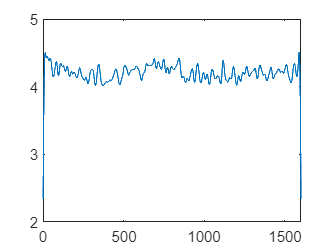

% stackedplot(Data_in');
plot(data(1,:));

sensorN =1:8;

num_step_train = floor(0.9*num_data);
train = data(sensorN,1:(num_step_train+1));
test = data(sensorN,(num_step_train+1):end);

## standardise thedata for zero mean and unit variance

mu = mean(train,2);
sigma = std(train,0,2);
std_train_data = (train - mu)./sigma;
XTrain = std_train_data(sensorN,1:end-1);
YTrain = std_train_data(sensorN,2:end);
num_features = 8;
num_responses = 8;
num_hidden_units = 512;%200 
layers = [sequenceInputLayer(num_features),lstmLayer(num_hidden_units),fullyConnectedLayer(num_responses),regressionLayer];
layers

layers =   1×4 Layer array with layers:

     1   ''   Sequence Input      Sequence input with 8 dimensions
     2   ''   LSTM                LSTM with 512 hidden units
     3   ''   Fully Connected     8 fully connected layer
     4   ''   Regression Output   mean-squared-error

options = trainingOptions('adam', 'MaxEpochs',500,...
    'GradientThreshold',1,'InitialLearnRate',0.005,...
    'LearnRateSchedule','piecewise','LearnRateDropPeriod',125,...
    'LearnRateDropFactor',0.2,'Verbose',0,'Plots','training-progress');
options

options =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9
      SquaredGradientDecayFactor: 0.999
                         Epsilon: 1e-08
                InitialLearnRate: 0.005
               LearnRateSchedule: 'piecewise'
             LearnRateDropFactor: 0.2
             LearnRateDropPeriod: 125
                L2Regularization: 0.0001
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: 1
                       MaxEpochs: 500
                   MiniBatchSize: 128
                         Verbose: 0
                VerboseFrequency: 50
                  ValidationData: []
             ValidationFrequency: 50
              ValidationPatience: Inf
                         Shuffle: 'once'
                  CheckpointPath: ''
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
            ExecutionEnvironment: 'auto'
       

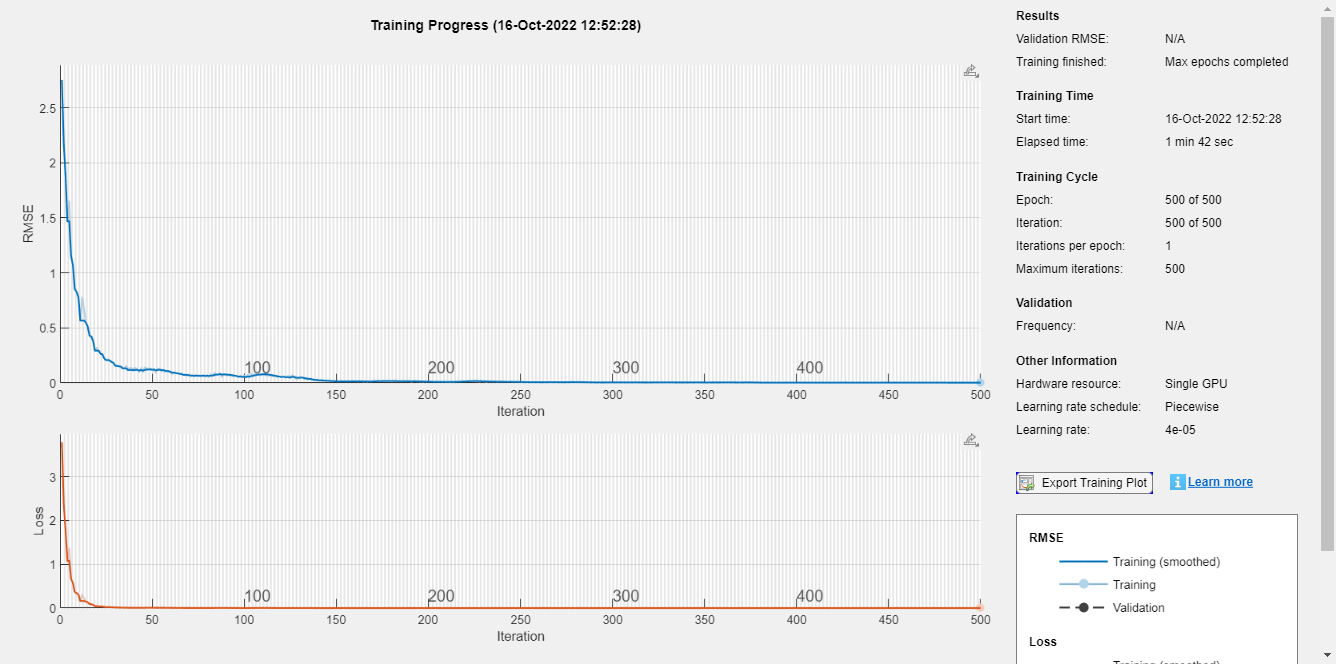

net = trainNetwork(XTrain,YTrain,layers,options);


 save('LSTMallnet_1tot_filter.mat') % uncomment when you want to save net trained
% network

## Load the LSTM network


load LSTMallnet.mat % load the trained net


## Prediction on test data

std_test_data = (test - mu)./sigma;% standardise the test data
XTest = std_test_data(sensorN ,1:end-1);
net = predictAndUpdateState(net, XTrain);
format long g;
[net, YPred] = predictAndUpdateState(net,YTrain(:,end)); % make first prediction using the last time step of training response : YTrain(end)
num_step_test = numel(XTest(1,:));
for i= 2:num_step_test
    [net,YPred(:,i)] = predictAndUpdateState(net, YPred(:,i-1));
end
% Destandardise the test data
YPred = YPred.*sigma + mu;
YTest = test(sensorN ,2:end);
rmse =sqrt(mean((YPred - YTest).^2));

## Prediction on training data

% std_test_data = (test - mu)./sigma;% standardise the test data
% XTrain = std_test_data(sensorN ,1:end-1);
net = predictAndUpdateState(net, XTrain);
format long g;
[net, YPred_train] = predictAndUpdateState(net,YTrain(:,1)); % make first prediction using the last time step of training response : YTrain(end)
num_step_train = numel(XTrain(1,:));% just for getting no  of time steps
for i= 2:num_step_train
    [net,YPred_train(:,i)] = predictAndUpdateState(net, YPred_train(:,i-1));
end
% Destandardise the test data
YPred_train = YPred_train.*sigma + mu;
YTrain = train(sensorN ,2:end);% since we are start prediction after 2nd time step using 1st time step as input
rmse_train =sqrt(mean((YPred_train - YTrain).^2));

## loading the noise free data

nfreemat = readmatrix('nfree-train.xlsx');
data_nfree = nfreemat(1,1:8);
data_nfree = [data_nfree; nfreemat(1,9:16)];
data_nfree = [data_nfree;nfreemat(1,17:24)];
for i =1: 1597
    data_nfree = [data_nfree;nfreemat(i,25:32)];
end
data_nfree = data_nfree';

% to save the workspace
% save('worksapce_LSTMall');

% load worksapce_LSTMall.mat

## Plot for prediction on test data

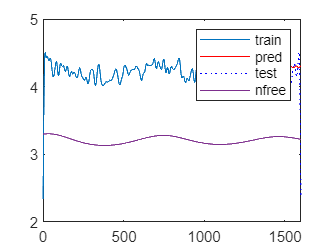

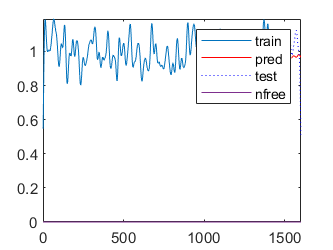

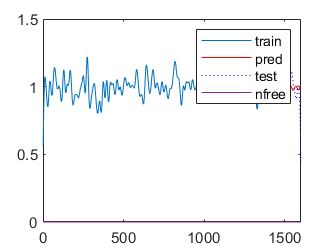

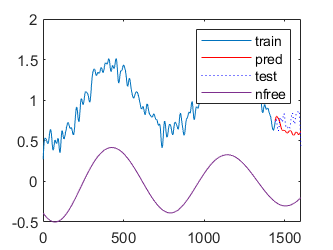

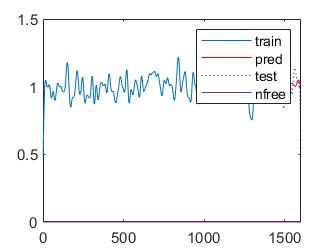

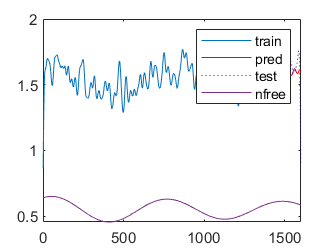

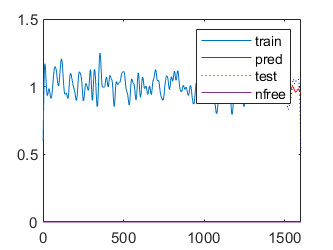

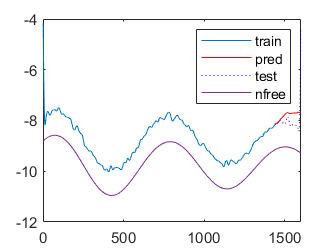

for i=1:8
figure(i);
plot(train(i,1:end-1));
hold on;
idx = num_step_train:(num_step_train+num_step_test);
plot(idx, [data(i,num_step_train),YPred(i,:)],'r')

plot(idx, [data(i,num_step_train),YTest(i,:)],'b:');
plot(data_nfree(i,:));
legend('train','pred','test','nfree');
hold off
end

## Plot for prediction on training data

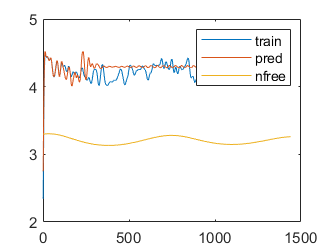

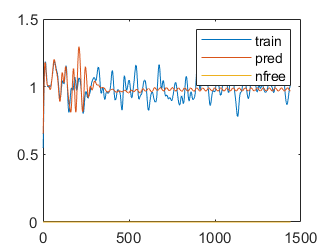

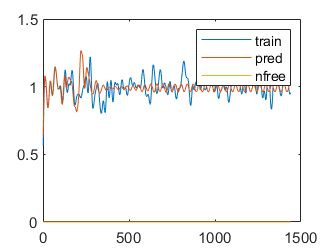

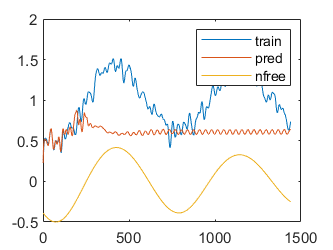

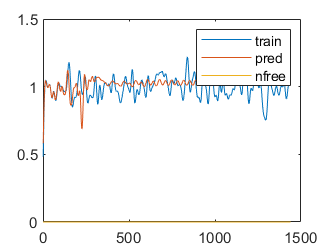

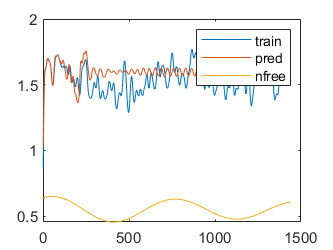

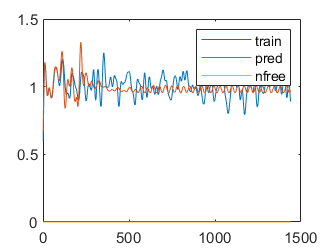

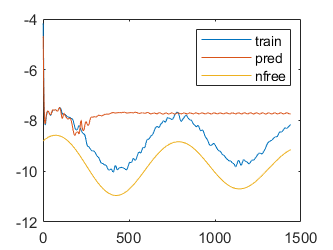

for i=1:8
figure(i+8);
plot(train(i,1:end-1));
hold on;
plot(YPred_train(i,:));
plot(data_nfree(i,1:1440));
legend('train','pred','nfree');
hold off
end